Derives Current based on Power

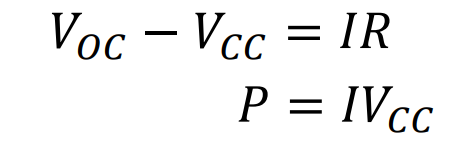

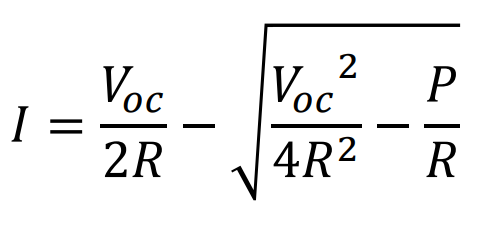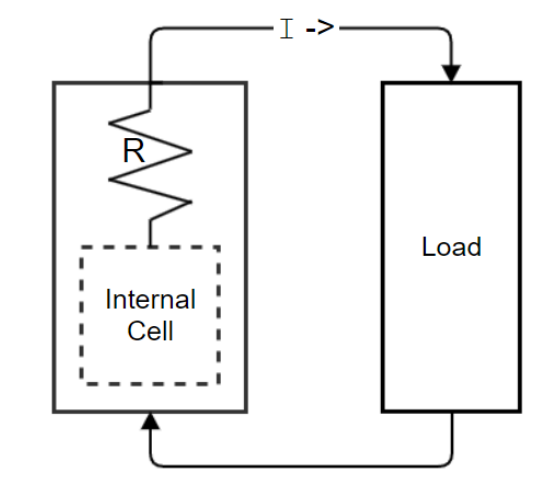

P = I^2 R is the basis of losses due to heat, this is how you find the I. Current is dynamic and increases(for the same power) as the pack discharges

Quantites Based off data sheet and batemo

[https://www.batemo.com/products/batemo-cell-explorer/murata-us18650-vtc6/](https://www.batemo.com/products/batemo-cell-explorer/murata-us18650-vtc6/) 

CellName = "VCT6";
CellHeight = 64.7/1000;%m
CellDiameter = 18.3/1000; %m
CellWeight = 47.3/1000; %kg
MassHeatCapacity = 900; %j/kg/k
HeatCapCell = 63;% j/k


MaxCellVoltage = 4.2;%volts
MinCellVoltage = 2.5;
VocCell = MaxCellVoltage;
DCresistance = 0.022;%ohms % this value should be looked into more, it varies a ton with energy demands. 
EnergyCell10ADraw = 35800;%joules, this value is abt 90% of the nominal capacity. 35800 was determined from the 
%lygte-info.dk website. The batemo power vs energy graph also shows about a
%10percent decrease in the range of 20kw to 30kw pack draws(28-43 per cell)

PackSeries = 138;
PackParralel = 5;
HeatCapPack = 63*PackSeries*PackParralel

HeatCapPack =        43470


InitialPackTemp = 25;
PackMaxVoltage = PackSeries * MaxCellVoltage; 
VocPack = PackMaxVoltage;
PackMin = PackSeries * MinCellVoltage

PackMin =    345


PackImpedance = DCresistance * PackSeries / PackParralel

PackImpedance =        0.6072


timeInput = [0 ;1 ; 10 ; 100 ; 200 ;]

timeInput =      0
     1
    10
   100
   200


PowerDemand = repmat(20000, height(timeInput), 1)

PowerDemand =        20000
       20000
       20000
       20000
       20000


TotalPackEnergy = PackSeries * PackParralel * EnergyCell10ADraw;
% VccPack=PowerDemand/PackImpedance;
% PeakPackPower ;
% EnergyConsumption;
% EnergyCell;



[https://lygte-info.dk/review/batteries2012/Sony%20US18650VTC6%203000mAh%20%28Green%29%20UK.html](https://lygte-info.dk/review/batteries2012/Sony%20US18650VTC6%203000mAh%20%28Green%29%20UK.html)

[https://www.e-cigarette-forum.com/threads/sony-vtc6-15a-3000mah-18650-bench-test-results-a-great-battery-equaling-hg2-30q.754649/](https://www.e-cigarette-forum.com/threads/sony-vtc6-15a-3000mah-18650-bench-test-results-a-great-battery-equaling-hg2-30q.754649/) 

[https://www.batemo.com/wp-content/uploads/general/performance_pictures/muRata_US18650VTC6_energy.png](https://www.batemo.com/wp-content/uploads/general/performance_pictures/muRata_US18650VTC6_energy.png) 

ETPIAT = table();
ETPIAT.timeInput = timeInput

ETPIAT = 5×1 table
    timeInput
    _________

         0   
         1   
        10   
       100   
       200   


ETPIAT.PowerDemand = PowerDemand%Example Pack entry

ETPIAT = 5×2 table
    timeInput    PowerDemand
    _________    ___________

         0          20000   
         1          20000   
        10          20000   
       100          20000   
       200          20000   




ETPIAT.VocPack = repmat(VocPack, length(ETPIAT.timeInput), 1)

ETPIAT = 5×3 table
    timeInput    PowerDemand    VocPack
    _________    ___________    _______

         0          20000        579.6 
         1          20000        579.6 
        10          20000        579.6 
       100          20000        579.6 
       200          20000        579.6 



ETPIAT.PackImpedance = repmat(PackImpedance, length(ETPIAT.timeInput), 1)

ETPIAT = 5×4 table
    timeInput    PowerDemand    VocPack    PackImpedance
    _________    ___________    _______    _____________

         0          20000        579.6        0.6072    
         1          20000        579.6        0.6072    
        10          20000        579.6        0.6072    
       100          20000        579.6        0.6072    
       200          20000        579.6        0.6072    


Table Creation

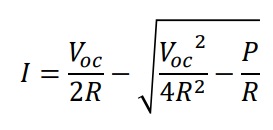

%ETPIA(:,5) = ETPIA(:,3)./2./ETPIA(:,4) - sqrt(ETPIA(:,3).^2 ./4./ETPIA(:,4).^2 - ETPIA(:,2)./ETPIA(:,4))
ETPIAT.Properties.VariableNames

ans = 1×4 cell array
    {'timeInput'}    {'PowerDemand'}    {'VocPack'}    {'PackImpedance'}



% Calculates Current using above formula and add it as a new column
ETPIAT.Current = ETPIAT.VocPack ./ 2 ./ ETPIAT.PackImpedance ...
    - sqrt(ETPIAT.VocPack.^2 ./ 4 ./ ETPIAT.PackImpedance.^2 - ETPIAT.PowerDemand ./ ETPIAT.PackImpedance)

ETPIAT = 5×5 table
    timeInput    PowerDemand    VocPack    PackImpedance    Current
    _________    ___________    _______    _____________    _______

         0          20000        579.6        0.6072        35.853 
         1          20000        579.6        0.6072        35.853 
        10          20000        579.6        0.6072        35.853 
       100          20000        579.6        0.6072        35.853 
       200          20000        579.6        0.6072        35.853 



%I = VocPack./2/PackImpedance - sqrt(VocPack^2 /4/PackImpedance^2 - PowerDemand/PackImpedance);

% This method of making this uses arrays. I think the ./ operator
%operator only means use values in the same row. the (:,5) or similar would
%mean cycling through all the column on the calculation. ./ makes it excel
%style math ish.



%ETPIA(:,6) = ETPIA(:,2)./ETPIA(:,5)
ETPIAT.ClosedCircutVoltage = ETPIAT.PowerDemand./ETPIAT.Current

ETPIAT = 5×6 table
    timeInput    PowerDemand    VocPack    PackImpedance    Current    ClosedCircutVoltage
    _________    ___________    _______    _____________    _______    ___________________

         0          20000        579.6        0.6072        35.853           557.83       
         1          20000        579.6        0.6072        35.853           557.83       
        10          20000        579.6        0.6072        35.853           557.83       
       100          20000        579.6        0.6072        35.853           557.83       
       200          20000        579.6        0.6072        35.853           557.83       


ETPIAT.ClosedCircutVoltage(isnan(ETPIAT.ClosedCircutVoltage)) = 0

ETPIAT = 5×6 table
    timeInput    PowerDemand    VocPack    PackImpedance    Current    ClosedCircutVoltage
    _________    ___________    _______    _____________    _______    ___________________

         0          20000        579.6        0.6072        35.853           557.83       
         1          20000        579.6        0.6072        35.853           557.83       
        10          20000        579.6        0.6072        35.853           557.83       
       100          20000        579.6        0.6072        35.853           557.83       
       200          20000        579.6        0.6072        35.853           557.83       


%ETPIA(:,7) = PackMin .* (ETPIA(:,3)- PackMin)./ETPIA(:,4);
ETPIAT.PeakPower = PackMin .*(VocPack-PackMin)./ETPIAT.PackImpedance

ETPIAT = 5×7 table
    timeInput    PowerDemand    VocPack    PackImpedance    Current    ClosedCircutVoltage    PeakPower
    _________    ___________    _______    _____________    _______    ___________________    _________

         0          20000        579.6        0.6072        35.853           557.83           1.333e+05
         1          20000        579.6        0.6072        35.853           557.83           1.333e+05
        10          20000        579.6        0.6072        35.853           557.83           1.333e+05
       100          20000        579.6        0.6072        35.853           557.83           1.333e+05
       200          20000        579.6        0.6072        35.853           557.83           1.333e+05


time_differences = diff(ETPIAT.timeInput)

time_differences =      1
     9
    90
   100


% Calculates the differences in the first column between consecutive rows
ETPIAT.timeDiff = [0; time_differences] % Uses 0 to indicate no previous difference for the first row

ETPIAT = 5×8 table
    timeInput    PowerDemand    VocPack    PackImpedance    Current    ClosedCircutVoltage    PeakPower    timeDiff
    _________    ___________    _______    _____________    _______    ___________________    _________    ________

         0          20000        579.6        0.6072        35.853           557.83           1.333e+05        0   
         1          20000        579.6        0.6072        35.853           557.83           1.333e+05        1   
        10          20000        579.6        0.6072        35.853           557.83           1.333e+05        9   
       100          20000        579.6        0.6072        35.853           557.83           1.333e+05       90   
       200  

ETPIAT.EnergyDiff = ETPIAT.timeDiff .* ETPIAT.PowerDemand

ETPIAT = 5×9 table
    timeInput    PowerDemand    VocPack    PackImpedance    Current    ClosedCircutVoltage    PeakPower    timeDiff    EnergyDiff
    _________    ___________    _______    _____________    _______    ___________________    _________    ________    __________

         0          20000        579.6        0.6072        35.853           557.83           1.333e+05        0              0  
         1          20000        579.6        0.6072        35.853           557.83           1.333e+05        1          20000  
        10          20000        579.6        0.6072        35.853           557.83           1.333e+05        9        1.8e+05  
       100          2000

JoulesTot = TotalPackEnergy;


% Calculates the cumulative sum of the EnergyDiff column
cumulativeEnergyConsumed = cumsum(ETPIAT.EnergyDiff, 'omitnan'); 

% Subtracts the cumulative energy consumed from the initial JoulesLeft
ETPIAT.JoulesLeft = JoulesTot - cumulativeEnergyConsumed;

Heat

ETPIAT.HeatGen = ETPIAT.Current.^2 .* ETPIAT.PackImpedance.*ETPIAT.timeDiff

ETPIAT = 5×11 table
    timeInput    PowerDemand    VocPack    PackImpedance    Current    ClosedCircutVoltage    PeakPower    timeDiff    EnergyDiff    JoulesLeft    HeatGen
    _________    ___________    _______    _____________    _______    ___________________    _________    ________    __________    __________    _______

         0          20000        579.6        0.6072        35.853           557.83           1.333e+05        0              0      2.4702e+07         0 
         1          20000        579.6        0.6072        35.853           557.83           1.333e+05        1          20000      2.4682e


CumulativeHeatGen = cumsum(ETPIAT.HeatGen,'omitNan');
ETPIAT.HeatEnergy = CumulativeHeatGen

ETPIAT = 5×12 table
    timeInput    PowerDemand    VocPack    PackImpedance    Current    ClosedCircutVoltage    PeakPower    timeDiff    EnergyDiff    JoulesLeft    HeatGen    HeatEnergy
    _________    ___________    _______    _____________    _______    ___________________    _________    ________    __________    __________    _______    __________

         0          20000        579.6        0.6072        35.853           557.83           1.333e+05        0              0      2.4702e+07         0              0
         1          20000        579.6        0.6072        35.8

ETPIAT.TempRise = ETPIAT.HeatEnergy/HeatCapPack

ETPIAT = 5×13 table
    timeInput    PowerDemand    VocPack    PackImpedance    Current    ClosedCircutVoltage    PeakPower    timeDiff    EnergyDiff    JoulesLeft    HeatGen    HeatEnergy    TempRise
    _________    ___________    _______    _____________    _______    ___________________    _________    ________    __________    __________    _______    __________    ________

         0          20000        579.6        0.6072        35.853           557.83           1.333e+05        0              0      2.4702e+07         0              0       